**Note:** Including quadratic damping force.

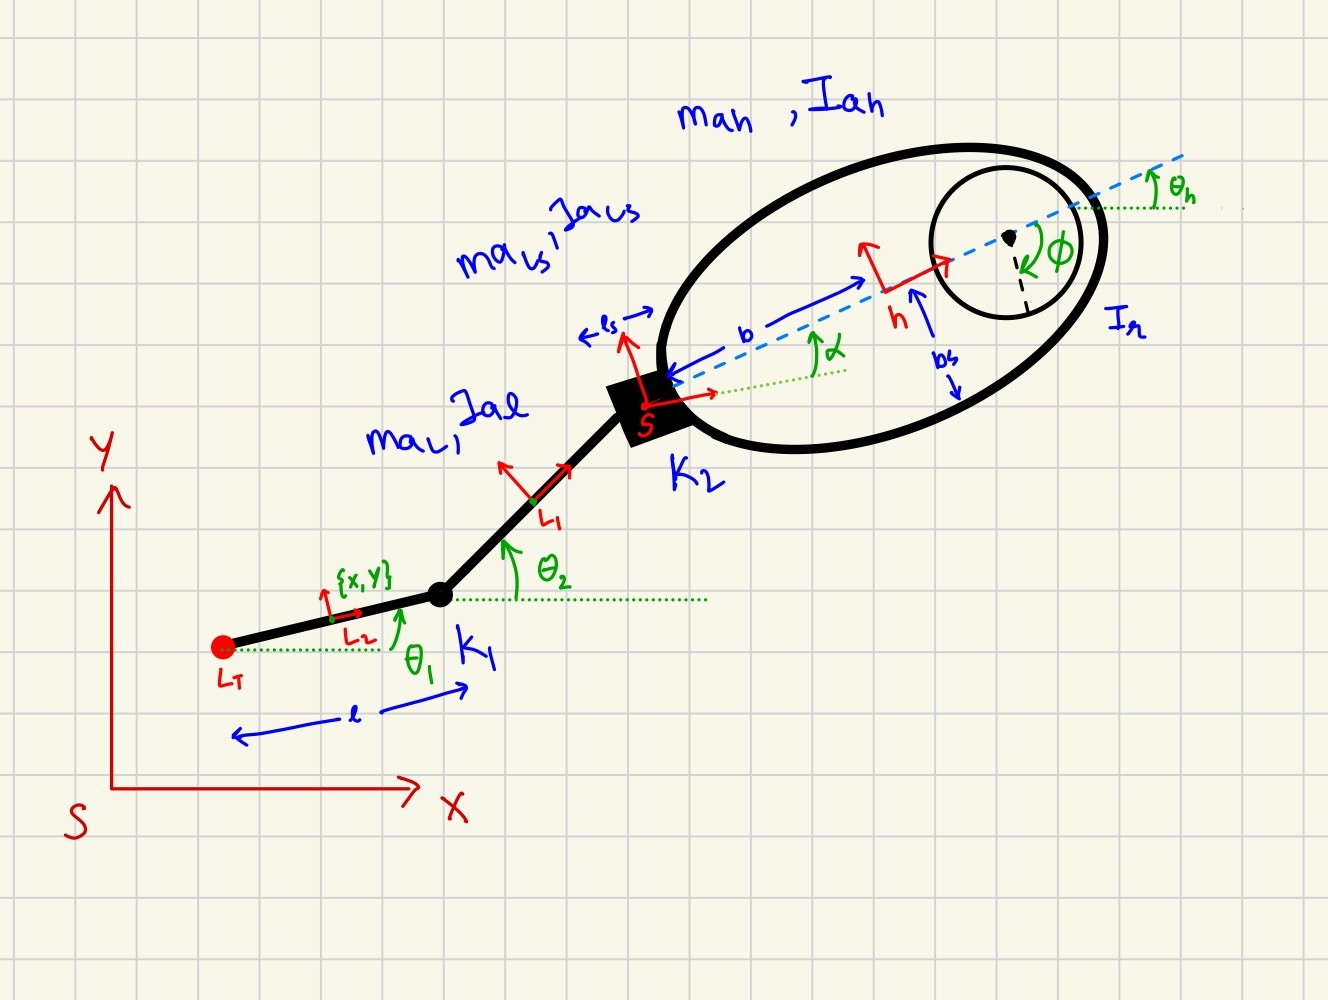

clc;
clear;
addpath("../../functions/")

%% 1. 
nl=2;      % number of links 
ns = nl+3; % number of states [x, y, theta_1, theta_2, theta_h]
nu = 2;    % number of inputs  [Alpha(t) phi_dd(t)]

#### Setup Constants

syms l1 l2 ls b positive
syms m_r I_r positive % rotor Mass and moment of inertia
syms K_1 K_2 positive% Stiffness for torsional springs
syms ma_l1x ma_l1y ma_l2x ma_l2y ma_hx ma_hy ma_lsx ma_lsy positive
syms Ia_hz Ia_l1z Ia_l2z Ia_lsz positive % total mass and moment of inertia including added mass
syms C_ly C_lx C_hx C_hy C_wl C_wh positive
Const_CS = [l1 l2 ls b ma_l1x ma_l1y ma_l2x ma_l2y ma_hx ma_hy ...
    ma_lsx ma_lsy Ia_hz Ia_l1z Ia_l2z Ia_lsz I_r K_1 K_2 C_ly C_lx C_hx C_hy C_wl C_wh]

$$Const\_CS = \left(\begin{array}{ccccccccccccccccccccccccc} l_{1} & l_{2} & \mathrm{ls} & b & {\mathrm{ma}}_{\mathrm{l1x}} & {\mathrm{ma}}_{\mathrm{l1y}} & {\mathrm{ma}}_{\mathrm{l2x}} & {\mathrm{ma}}_{\mathrm{l2y}} & {\mathrm{ma}}_{\mathrm{hx}} & {\mathrm{ma}}_{\mathrm{hy}} & {\mathrm{ma}}_{\mathrm{lsx}} & {\mathrm{ma}}_{\mathrm{lsy}} & {\mathrm{Ia}}_{\mathrm{hz}} & {\mathrm{Ia}}_{\mathrm{l1z}} & {\mathrm{Ia}}_{\mathrm{l2z}} & {\mathrm{Ia}}_{\mathrm{lsz}} & I_{r} & K_{1} & K_{2} & C_{\mathrm{ly}} & C_{\mathrm{lx}} & C_{\mathrm{hx}} & C_{\mathrm{hy}} & C_{\mathrm{wl}} & C_{\mathrm{wh}} \end{array}\right)$$

#### Setup state variables and functions dependent on time

syms x x_dot x_ddot y y_dot y_ddot 
syms Phi(t) Alpha(t)
s= sym('s',[ns,1]); s_dot= sym('ss',[ns,1]); s_ddot= sym('dds',[ns,1]);
s(1,1) = x; s_dot(1,1) = x_dot; s_ddot(1,1) = x_ddot;
s(2,1) = y; s_dot(2,1) = y_dot; s_ddot(2,1) = y_ddot;
for i=1:nl
    eval("syms theta_"+i);
    s(i+2,1) = eval("theta_"+i);
    eval("syms theta_dot_"+i+" theta_ddot_"+i);
    s_dot(i+2,1) =eval("theta_dot_"+i);
    s_ddot(i+2,1) =eval("theta_ddot_"+i);
end
syms theta_h theta_dot_h theta_ddot_h   
s(end,1) = theta_h; s_dot(end,1) = theta_dot_h;
s_ddot(end,1) = theta_ddot_h;

syms phi_ddot phi_dot phi alpha alpha_dot alpha_ddot    % inputs
in_dd = [phi_ddot;alpha_ddot]; in_d = [phi_dot;alpha_dot];
in = [phi;alpha];

% we need capital and small variables as one is dependent on
% time other is not: for derivating, solving and substituting in equations

syms X(t) Y(t) Theta_1(t) Theta_h(t) Theta_2(t)
S(:,1) = [X;Y;Theta_1(t);Theta_2(t);Theta_h(t)];  
S_dot(:,1) = diff(S,t);           
S_ddot(:,1) = diff(S_dot,t);

In(:,1) = [Phi;Alpha];   % time dependent input 
In_d(:,1) = diff(In,t);
In_dd(:,1) = diff(In_d,t);

% expr1 = subsFunction2expression(S_dot,[S;In],[s;in],[s_dot;in_d],[s_ddot;in_dd]);  % substitution for clean notation
expr = subsFunction2expression(S,[S;In],[s;in],[s_dot;in_d],[s_ddot;in_dd]);  % substitution for clean notation
% expr2 = subsFunction2expression(S_ddot,[S;In],[s;in],[s_dot;in_d],[s_ddot;in_dd]);  % substitution for clean notation
displayFormula('q = expr')

$$q=\left(\begin{array}{c} x\\ y\\ \theta_{1}\\ \theta_{2}\\ \theta_{h} \end{array}\right)$$

**Positions, Jacobians and velocities for each body COM**

% COM positions (WORLD)
% Link_1 (your Js1 was identity in x,y => COM assumed at base point)
r_l1 = [S(1,1); S(2,1)];

% Link_2 COM (+/- 0.5*l1, 0.5*l2)
r_l2 = r_l1 + [ 0.5*l1*cos(S(3,1)) + 0.5*l2*cos(S(4,1));
                0.5*l1*sin(S(3,1)) + 0.5*l2*sin(S(4,1)) ];

% Short Link COM (l2 full + 0.5*ls at angle (S(5,1)+alpha))
r_ls = r_l2 + [ 0.5*l2*cos(S(4,1)) + 0.5*ls*cos(S(5,1) + In(2,1));
                0.5*l2*sin(S(4,1)) + 0.5*ls*sin(S(5,1) + In(2,1))];

% Head COM (ls full at (S(5,1)+alpha) + b at S(5,1))
r_h  = r_ls + [ 0.5*ls*cos(S(5,1) + In(2,1)) + b*cos(S(5,1));
                0.5*ls*sin(S(5,1) + In(2,1)) + b*sin(S(5,1))];

% Jacobians wrt q (2x5) and alpha direction (2x1)
Jq1 = jacobian(r_l1, S);   ja1 = diff(r_l1, In(2,1));
Jq2 = jacobian(r_l2, S);   ja2 = diff(r_l2, In(2,1));
Jq3 = jacobian(r_ls, S);   ja3 = diff(r_ls, In(2,1));
Jq4 = jacobian(r_h, S);   ja4 = diff(r_h, In(2,1));

% Point velocities (WORLD) = Jq*qd + (Ja*alphad

v_l1 = simplify(Jq1*S_dot + ja1*In_d(2,1));   % ja1 is zero
v_l2 = simplify(Jq2*S_dot + ja2*In_d(2,1));   % ja2 is zero
v_ls = simplify(Jq3*S_dot + ja3*In_d(2,1));   % depends on alphad
v_h  = simplify(Jq4*S_dot + ja4*In_d(2,1));   % depends on alphad

expr1 = subsFunction2expression(Jq2,[S;In],[s;in],[s_dot;in_d],[s_ddot;in_dd]);   % substitution for clean notation
expr2 = subsFunction2expression(Jq3,[S;In],[s;in],[s_dot;in_d],[s_ddot;in_dd]);   % substitution for clean notation
expr3 = subsFunction2expression(Jq4,[S;In],[s;in],[s_dot;in_d],[s_ddot;in_dd]);   % substitution for clean notation
displayFormula('Jql_1link = Jq1')

$${\mathrm{Jql}}_{\mathrm{1link}}=\left(\begin{array}{ccccc} 1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 \end{array}\right)$$

displayFormula('Jq2_2link = expr1')

$${\mathrm{Jq}}_{2,\mathrm{2link}}=\left(\begin{array}{ccccc} 1 & 0 & -\frac{l_{1}\,\sin\left(\theta_{1}\right)}{2} & -\frac{l_{2}\,\sin\left(\theta_{2}\right)}{2} & 0\\ 0 & 1 & \frac{l_{1}\,\cos\left(\theta_{1}\right)}{2} & \frac{l_{2}\,\cos\left(\theta_{2}\right)}{2} & 0 \end{array}\right)$$

displayFormula('Jq3_slink = expr2')

$${\mathrm{Jq}}_{3,\mathrm{slink}}=\left(\begin{array}{ccccc} 1 & 0 & -\frac{l_{1}\,\sin\left(\theta_{1}\right)}{2} & -l_{2}\,\sin\left(\theta_{2}\right) & -\frac{\mathrm{ls}\,\sin\left(\alpha +\theta_{h}\right)}{2}\\ 0 & 1 & \frac{l_{1}\,\cos\left(\theta_{1}\right)}{2} & l_{2}\,\cos\left(\theta_{2}\right) & \frac{\mathrm{ls}\,\cos\left(\alpha +\theta_{h}\right)}{2} \end{array}\right)$$

displayFormula('Jq4_hlink = expr3')

$${\mathrm{Jq}}_{4,\mathrm{hlink}}=\left(\begin{array}{ccccc} 1 & 0 & -\frac{l_{1}\,\sin\left(\theta_{1}\right)}{2} & -l_{2}\,\sin\left(\theta_{2}\right) & -\mathrm{ls}\,\sin\left(\alpha +\theta_{h}\right)-b\,\sin\left(\theta_{h}\right)\\ 0 & 1 & \frac{l_{1}\,\cos\left(\theta_{1}\right)}{2} & l_{2}\,\cos\left(\theta_{2}\right) & \mathrm{ls}\,\cos\left(\alpha +\theta_{h}\right)+b\,\cos\left(\theta_{h}\right) \end{array}\right)$$

### **2. Translation KE**

ms_l1 = diag([ma_l1x , ma_l1y]);
ms_l2 = diag([ma_l2x , ma_l2y]);
ms_ls = diag([ma_lsx , ma_lsy]);
ms = diag([ma_hx, ma_hy]);

T1 = 0.5*((v_l1.')*ms_l1*v_l1); 
T2 = 0.5*((v_l2.')*ms_l2*v_l2);
T3 = 0.5*((v_ls.')*ms_ls*v_ls);
T4 = 0.5*((v_h.')*ms*v_h);

T = (T1+T2+T3+T4);
expr = subsFunction2expression(T,[S;In],[s;in],[s_dot;in_d],[s_ddot;in_dd]);    % substitution for clean notation
% displayFormula('TE = expr')
% eval(subs(exprT,st_repl,nm_repl))

### 3. Rotational KE

I(1,1) = Ia_l1z;
I(2,2) = Ia_l2z;  
I(3,3) = Ia_lsz; 
I(4,4) =Ia_hz;
I(5,5) = I_r;
Sdot_r = [S_dot(3:4,1);S_dot(5,1)+In_d(2,1);S_dot(5,1);S_dot(5,1)+In_d(1,1)];
R = 0.5*Sdot_r.'*I*Sdot_r;
expr = subsFunction2expression(R,[S;In],[s;in],[s_dot;in_d],[s_ddot;in_dd]);     % substitution for clean notation
displayFormula('RE = expr')

$$\mathrm{RE}=\frac{{\mathrm{Ia}}_{\mathrm{l1z}}\,{{\dot{\theta }}_{1}}^{2}}{2}+\frac{{\mathrm{Ia}}_{\mathrm{l2z}}\,{{\dot{\theta }}_{2}}^{2}}{2}+\frac{{\mathrm{Ia}}_{\mathrm{hz}}\,{{\dot{\theta }}_{h}}^{2}}{2}+{\mathrm{Ia}}_{\mathrm{lsz}}\,\left(\dot{\alpha }+{\dot{\theta }}_{h}\right)\,\left(\frac{\dot{\alpha }}{2}+\frac{{\dot{\theta }}_{h}}{2}\right)+I_{r}\,\left(\frac{\dot{\varphi }}{2}+\frac{{\dot{\theta }}_{h}}{2}\right)\,\left(\dot{\varphi }+{\dot{\theta }}_{h}\right)$$

% eval(subs(exprR,st_repl,nm_repl))

### 4. Conservative forces

PE = 0.5*K_1*(S(3,1)-S(4,1))^2 + 0.5*K_2*(S(4,1)-In(2,1)-S(5,1))^2;
V = PE;    %simplify(expand(0.5*Sa.'*A*Sa))
exprP = subsFunction2expression(V,[S;In],[s;in],[s_dot;in_d],[s_ddot;in_dd]);    % substitution for clean notation
% displayFormula('VE = expr')
% eval(subs(exprP,st_repl,nm_repl))

### 5. Lagrangian 


$$L=\textrm{TE}+\textrm{RE}-\textrm{VE}$$
   

L = T+R-V;
exprL = subsFunction2expression(L,[S;In],[s;in],[s_dot;in_d],[s_ddot;in_dd]);    % substitution for clean notation
% displayFormula('Lagr = expr')
% eval(subs(exprL,st_repl,nm_repl))

### 8. Substitution  dx, dy --> u (u_tail)

syms u u_dot
xdot = u*cos(s(3,:))-0.5*l1*s_dot(3,:)*sin(s(3,:));
ydot = u*sin(s(3,:))+0.5*l1*s_dot(3,:)*cos(s(3,:));
xddot = u_dot*cos(s(3,:)) - u*s_dot(3,:)*sin(s(3,:))...
    -0.5*l1*s_ddot(3,:)*sin(s(3,:))-0.5*l1*(s_dot(3,1).^2)*cos(s(3,:));
yddot = u_dot*sin(s(3,:)) + u*s_dot(3,:)*cos(s(3,:))...
    +0.5*l1*s_ddot(3,:)*cos(s(3,:))-0.5*l1*(s_dot(3,1).^2)*sin(s(3,:));
xdx = [xdot;ydot;xddot;yddot];
xde = {'dx = expr','dy = expr','ddx = expr','ddy = expr'};
for i=1:4
    expr = subsFunction2expression(xdx(i,1),[S;In],[s;in],[s_dot;in_d],[s_ddot;in_dd]);
    displayFormula(xde{i})
    % eval(subs(expr,st_replu,nm_replu))
end

$$\mathrm{dx}=u\,\cos\left(\theta_{1}\right)-\frac{l_{1}\,{\dot{\theta }}_{1}\,\sin\left(\theta_{1}\right)}{2}$$

$$\mathrm{dy}=u\,\sin\left(\theta_{1}\right)+\frac{l_{1}\,{\dot{\theta }}_{1}\,\cos\left(\theta_{1}\right)}{2}$$

$$\mathrm{ddx}=-\frac{l_{1}\,\cos\left(\theta_{1}\right)\,{{\dot{\theta }}_{1}}^{2}}{2}-u\,\sin\left(\theta_{1}\right)\,{\dot{\theta }}_{1}+\dot{u}\,\cos\left(\theta_{1}\right)-\frac{l_{1}\,{\ddot{\theta }}_{1}\,\sin\left(\theta_{1}\right)}{2}$$

$$\mathrm{ddy}=-\frac{l_{1}\,\sin\left(\theta_{1}\right)\,{{\dot{\theta }}_{1}}^{2}}{2}+u\,\cos\left(\theta_{1}\right)\,{\dot{\theta }}_{1}+\dot{u}\,\sin\left(\theta_{1}\right)+\frac{l_{1}\,{\ddot{\theta }}_{1}\,\cos\left(\theta_{1}\right)}{2}$$

### 5. Generalized forces

 I) Lagrange multiplier (Non-holonomic Constraint)   $v=b\dot{\;\theta \;} =-\dot{x} \;\sin \;\theta \;+\dot{y} \;\cos \;\theta$

Ck = sym(zeros(1,ns)); 
Ck(1,1) = -sin(s(3,1)); Ck(1,2) = cos(s(3,1)); Ck(1,3)=-0.5*l1;  Ck(1,4)=0;
expr = subsFunction2expression(Ck,[S;In],[s;in],[s_dot;in_d],[s_ddot;in_dd]);
displayFormula('C_k = expr')

$$C_{k}=\left(\begin{array}{ccccc} -\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & -\frac{l_{1}}{2} & 0 & 0 \end{array}\right)$$

% eval(subs(expr,st_replu,nm_replu))

II) Quadratic damping forces (NO Rayleigh) + Quadratic rotational damping

% S_dot
% --- rotations ---
Rbw = @(th) [cos(th) sin(th); -sin(th) cos(th)];   % world -> body
Rwb = @(th) Rbw(th).';                              % body  -> world

% --- convert to BODY frame velocities (so drag coefficients stay body-fixed) ---
vb_l1 = Rbw(S(3,1))          * v_l1;
vb_l2 = Rbw(S(4,1))          * v_l2;
vb_ls = Rbw(S(5,1)+In(2,1))  * v_ls;   % short link orientation = theta_h + alpha
vb_h  = Rbw(S(5,1))          * v_h;    % head orientation = theta_h

% --- quadratic drag coefficients (translation) ---
% syms C_ly C_lx C_hx C_hy positive
Cl = diag([C_lx, C_ly]);     % for links
Ch = diag([C_hx, C_hy]);     % for head

% Smooth absolute value to keep symbolic/optimization happy at v=0
eps_v = sym(1e-6);
abs_s = @(z) sqrt(z.^2 + eps_v);  % ~|z| but smooth

% --- quadratic drag in BODY frame: F = -C*(|v| .* v) (componentwise) ---
Fbl1 = -Cl * ( abs_s(vb_l1) .* vb_l1 );
Fbl2 = -Cl * ( abs_s(vb_l2) .* vb_l2 );
Fbls = -Cl * ( abs_s(vb_ls) .* vb_ls );
Fbh  = -Ch * ( abs_s(vb_h ) .* vb_h  );

% --- back to WORLD frame forces (so they match Js* which is world-kinematics) ---
Fwl1 = Rwb(S(3,1))         * Fbl1;
Fwl2 = Rwb(S(4,1))         * Fbl2;
Fwls = Rwb(S(5,1)+In(2,1)) * Fbls;
Fwh  = Rwb(S(5,1))         * Fbh;

% --- generalized forces from translational drag ---
Q_l1 = Jq1.' * Fwl1;
Q_l2 = Jq2.' * Fwl2;
Q_ls = Jq3.' * Fwls;
Q_h  = Jq4.' * Fwh;

Q_trans = simplify(Q_l1 + Q_l2 + Q_ls + Q_h);   % nb x 1

%% --- Quadratic ROTATIONAL damping (pure torques) ---
% dS = [ẋ; ẏ; θ̇1; θ̇2; (θ̇h+α̇); θ̇h]

% syms C_wl C_wh positive   % rotational quadratic damping coeffs
Q_rot = sym(zeros(ns,1));
Q_rot(3) = -C_wl  * abs_s(S_dot(3) ) * S_dot(3);
Q_rot(4) = -C_wl  * abs_s(S_dot(4) ) * S_dot(4);
% Q_rot(5) = -0 * abs_s(S_dot(5)+ In_d(2,1)) * (S_dot(5)+ In_d(2,1));   % assumed no rot drag for short link
Q_rot(5) = -C_wh  * abs_s(S_dot(5) ) * S_dot(5);

% --- total damping generalized force ---
Q_dq = simplify(Q_trans + Q_rot);

Q_dq = subsFunction2expression(Q_dq,[S;In],[s;in],[s_dot;in_d],[s_ddot;in_dd]);
Qdq  = subs(Q_dq,[s_dot(1:2,1)],[xdot;ydot]);
Qdq  = simplify(Qdq);


###   7. Euler-Lagrange Equation

#### 
$$\frac{\mathrm{d}}{\mathrm{d}t}\left(\frac{\partial }{\partial \dot{q} }\left(L\right)\right)-\frac{\partial }{\partial q}\left(L\right)=\lambda \;{C^T }_k +Q_{k_q } +\Gamma$$


Eq=sym(zeros(ns,1));
for i=1:length(S_dot)
    Eq(i,1) = diff(diff(L,S_dot(i,1)),t) - diff(L,S(i,1));
end
eq = subsFunction2expression(Eq,[S;In],[s;in],[s_dot;in_d],[s_ddot;in_dd]);   % substitutin all 
% eval(subs(eq,st_replu,nm_replu))
syms lambda
eq1 = eq - lambda*Ck.' - Qdq;
% displayFormula('EQ_L = eq1')

### Substitute dx, dy --> u in equation of motion

eq1 = subs(eq1,[s_dot(1:2,1);s_ddot(1:2,1)],[xdot;ydot;xddot;yddot]);
% displayFormula('eq1')
% eval(subs(eq1,st_replu,nm_replu))

### 9. Solve for $\lambda$ and reduce EOM

eq_lam = eq1(1,1)*sin(s(3,:)) - eq1(2,1)*cos(s(3,1));
lam1 = solve(eq_lam,lambda);
% displayFormula('lambda = lam1')
% eval(subs(lam1,st_replu,nm_replu))
eqn_1 = simplify(eq1(1,1)*cos(s(3,:)) + eq1(2,1)*sin(s(3,1)));
eqn = [eqn_1;eq1(3:end,1)];
eqn = simplify(subs(eqn,lambda,lam1));

eqn_s =simplify(expand(eqn));
% displayFormula('eqn_s')

### 10. E.O.M by extracting Mass matrix, gravitational, coriollis and centrifugal terms

Qd = [u;s_dot(3:end,:)];
Qdd= [u_dot;s_ddot(3:end,:)];
B = eqn;
[M,C,G] = extract_dynamics(B,Qd,Qdd);

 display(simplify(G))

display(simplify(M))

display(simplify(C))

symvar(M)

$$ans = \left(\begin{array}{ccccccccccccccccccccc} I_{r} & {\mathrm{Ia}}_{\mathrm{hz}} & {\mathrm{Ia}}_{\mathrm{l1z}} & {\mathrm{Ia}}_{\mathrm{l2z}} & {\mathrm{Ia}}_{\mathrm{lsz}} & \alpha & b & l_{1} & l_{2} & \mathrm{ls} & {\mathrm{ma}}_{\mathrm{hx}} & {\mathrm{ma}}_{\mathrm{hy}} & {\mathrm{ma}}_{\mathrm{l1x}} & {\mathrm{ma}}_{\mathrm{l1y}} & {\mathrm{ma}}_{\mathrm{l2x}} & {\mathrm{ma}}_{\mathrm{l2y}} & {\mathrm{ma}}_{\mathrm{lsx}} & {\mathrm{ma}}_{\mathrm{lsy}} & \theta_{1} & \theta_{2} & \theta_{h} \end{array}\right)$$

symvar(C)

$$ans = \left(\begin{array}{ccccccccccccccccccccccccccc} C_{\mathrm{hx}} & C_{\mathrm{hy}} & C_{\mathrm{lx}} & C_{\mathrm{ly}} & C_{\mathrm{wh}} & C_{\mathrm{wl}} & \alpha & \dot{\alpha } & b & l_{1} & l_{2} & \mathrm{ls} & {\mathrm{ma}}_{\mathrm{hx}} & {\mathrm{ma}}_{\mathrm{hy}} & {\mathrm{ma}}_{\mathrm{l1x}} & {\mathrm{ma}}_{\mathrm{l1y}} & {\mathrm{ma}}_{\mathrm{l2x}} & {\mathrm{ma}}_{\mathrm{l2y}} & {\mathrm{ma}}_{\mathrm{lsx}} & {\mathrm{ma}}_{\mathrm{lsy}} & \theta_{1} & \theta_{2} & {\dot{\theta }}_{1} & {\dot{\theta }}_{2} & {\dot{\theta }}_{h} & \theta_{h} & u \end{array}\right)$$

symvar(G)

$$ans = \left(\begin{array}{cccccccccccccccccccccccccc} C_{\mathrm{hx}} & C_{\mathrm{hy}} & C_{\mathrm{ly}} & I_{r} & {\mathrm{Ia}}_{\mathrm{lsz}} & K_{1} & K_{2} & \alpha & \ddot{\alpha } & \dot{\alpha } & b & l_{1} & l_{2} & \mathrm{ls} & {\mathrm{ma}}_{\mathrm{hx}} & {\mathrm{ma}}_{\mathrm{hy}} & {\mathrm{ma}}_{\mathrm{lsx}} & {\mathrm{ma}}_{\mathrm{lsy}} & \ddot{\varphi } & \theta_{1} & \theta_{2} & {\dot{\theta }}_{1} & {\dot{\theta }}_{2} & {\dot{\theta }}_{h} & \theta_{h} & u \end{array}\right)$$

#### Create a Matlab Function

%% constants
filename = "Balanced_Cs_wAddedMass_4link_v1";
sts(1:7) = [Qd(1,1);Qd(2,1);s(3,1);Qd(3,1);s(4,1);Qd(4,1);s(5,1)];
% sts = [u theta_dot_1 theta_1, theta_dot_2 theta_2, theta_dot_h theta_h]
inp = [phi_ddot;phi_dot;alpha_ddot;alpha_dot;alpha];
const = Const_CS;
Cn_qd = C*Qd;
matlabFunction(M,Cn_qd,G,'file',filename,'Vars',{sts,const,inp}); 


%% Parameters for the Chaplygin Sleigh with servo actuated 3 link tail
rho =997;   %  density
AM = 1;

% For Head link 
Const1.b = 0.075;                                    % length major axis (m)
Const1.bs = 0.035;                                    % length minor axis (m)
m_h = 0.44;                                   % mass (kg)
I_h = m_h*(Const1.b^2+Const1.bs^2)/4;     % m.o.i (Kg/m^2) 
Const1.ma_hx = m_h + AM*pi*rho*(Const1.bs)^2*Const1.b;          % added mass (kg)
Const1.ma_hy = m_h + AM*pi*rho*(Const1.b)^3;         % added mass (kg)
Const1.Ia_hz = I_h + AM*(1/8)*pi*rho*Const1.b*(Const1.b^2-Const1.bs^2)^2;% added m.o.i (Kg/m^2)

% For link1 
Const1.l1 = 0.048;                           % length (m)
m_l1 = 0.01/2;                        % mass (kg)
I_l1 = (1/12)*m_l1*Const1.l1^2;  % m.o.i (Kg/m^2)
Const1.ma_l1x = m_l1 + AM*0;                           % added mass (kg)
Const1.ma_l1y = m_l1 + AM*pi*rho*0.075*(Const1.l1/2)^2;        % added mass (kg)
Const1.Ia_l1z = I_l1 + AM*(1/8)*pi*rho*0.075*(Const1.l1/2)^4; % added m.o.i (Kg/m^2)

% For link2 
Const1.l2 = 0.048;                           % length (m)
m_l2 = 0.01/2;                        % mass (kg)
I_l2 = (1/12)*m_l2*Const1.l2^2;  % m.o.i (Kg/m^2) 
Const1.ma_l2x = m_l2 + AM*0;                           % added mass (kg)
Const1.ma_l2y = m_l2 + AM*pi*rho*0.075*(Const1.l2/2)^2;      % added mass (kg)
Const1.Ia_l2z = I_l2 + AM*(1/8)*pi*rho*0.075*(Const1.l2/2)^4; % added m.o.i (Kg/m^2)

% For short link 
Const1.ls = 0.015;                            % length (m)
m_ls = 0.01;                        % mass (kg)
I_ls = (1/12)*m_ls*Const1.ls^2;  % m.o.i (Kg/m^2) 
Const1.ma_lsx = m_ls + AM*0;                           % added mass (kg)
Const1.ma_lsy = m_ls + AM*pi*rho*0.075*(Const1.ls/2)^2;       % added mass (kg)
Const1.Ia_lsz = I_ls + AM*(1/8)*pi*rho*0.075*(Const1.ls/2)^4; % added m.o.i (Kg/m^2)

% For rotor 
Const1.c = 0.03;                             % length (m)
Const1.m_r = 0.1;                            % mass (kg)
Const1.I_r = Const1.m_r*0.027^2;              % m.o.i (Kg/m^2) 

% constant rayleigh dissipation 
Const1.C_hx = 0.46;
Const1.C_hy = 10;
Const1.C_lx = 0;
Const1.C_ly = 10;
Const1.C_wl = 0.2;
Const1.C_wh = 0.4;
Const1.K_1 = 0.4;
Const1.K_2 = 0.7;

Const_NCS = [Const1.l1 Const1.l2 Const1.ls Const1.b Const1.ma_l1x Const1.ma_l1y...
    Const1.ma_l2x Const1.ma_l2y Const1.ma_hx Const1.ma_hy Const1.ma_lsx Const1.ma_lsy...
    Const1.Ia_hz Const1.Ia_l1z Const1.Ia_l2z Const1.Ia_lsz Const1.I_r Const1.K_1 Const1.K_2...
    Const1.C_ly Const1.C_lx Const1.C_hx Const1.C_hy Const1.C_wl Const1.C_wh]

Const_NCS =     0.0480    0.0480    0.0150    0.0750    0.0050    0.1403    0.0050    0.1403    0.7278    1.7614    0.0100    0.0232    0.0013    0.0000    0.0000    0.0000    0.0001    0.4000    0.7000   10.0000         0    0.4600   10.0000    0.2000    0.4000



st_repl = [u;s_dot(3);s(3);s_dot(4);s(4);s_dot(5);s(5);in(2);...
    in_d(2);in_dd(2);in_dd(1);Const_CS.'];
nm_repl = [0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7, 0.8, 0.9,...
    1.0, 1.1, Const_NCS].';

eval(subs(M,st_repl,nm_repl))

ans =     0.8628    0.0169    0.0068   -0.0137
    0.0169    0.0043    0.0038    0.0054
    0.0068    0.0038    0.0036    0.0054
   -0.0137    0.0054    0.0054    0.0103


eval(subs(C*Qd,st_repl,nm_repl))

ans =     0.0064
    0.0067
    0.0305
    0.1445


eval(subs(G,st_repl,nm_repl))

ans =    -0.0233
   -0.0805
   -0.6202
    0.7001


eval(subs(C*Qd+G,st_repl,nm_repl))

ans =    -0.0169
   -0.0738
   -0.5897
    0.8446


eval(subs(C,st_repl,nm_repl))

ans =     0.7741   -0.0272   -0.0422   -0.0812
   -0.0009    0.0411    0.0008   -0.0029
   -0.0093    0.0013    0.0811   -0.0021
    0.0008    0.0021    0.0019    0.2387


 II) Dissipation forces $Q_{k_q } =-\;\frac{\partial }{\partial \dot{q} }R_w$

% syms C_ly C_lx C_hx C_hy
% % velocity of each link in its body frame
% Rbw = @(x) [cos(x) sin(x);-sin(x) cos(x)];
% v_l1 = Js1*dS; vb_l1 = Rbw(S(3,1))*v_l1;  
% v_l2 = Js2*dS; vb_l2 = Rbw(S(4,1))*v_l2; 
% v_ls = Js3*dS; vb_ls = Rbw(In(2,1)+S(5,1))*v_ls; 
% v_h = Js4*dS;  vb_h = Rbw(S(5,1))*v_h; 
% 
% % Rayleigh dissipation due to each body
% Cl = [C_lx 0;0 C_ly];
% Ch = [C_hx 0;0 C_hy];
% R_l1 = 0.5*(vb_l1.')*Cl*vb_l1;
% R_l2 = 0.5*(vb_l2.')*Cl*vb_l2;
% R_ls = 0.5*(vb_ls.')*Cl*vb_ls;
% R_h = 0.5*(vb_h.')*Ch*vb_h;
% Q_dq = [-jacobian(expand(R_l1),S_dot).',...
%     -jacobian(expand(R_l2),S_dot).',...
%     -jacobian(expand(R_ls),S_dot).',...
%     -jacobian(expand(R_h),S_dot).'];
% 
% Q_dq = subsFunction2expression(Q_dq,[S;In],[s;in],[s_dot;in_d],[s_ddot;in_dd]);   
% Qdq = subs(Q_dq,[s_dot(1:2,1)],[xdot;ydot]);
% Qdq = sum(simplify(Qdq),2);
% displayFormula('Q_k_q = Q_dq')
% eval(subs(Qdq,st_replu,nm_replu))